# [**Waves and disorder**](https://chaos.if.uj.edu.pl/~delande/Lectures/)

## Lectures on Waves in disordered media: transport and localization

### [Classical diffusive dynamics - Lectures on Waves in disordered media: transport and localization](https://chaos.if.uj.edu.pl/~delande/Lectures/?classical-diffusive-dynamics,17)

[](https://chaos.if.uj.edu.pl/~delande/Lectures/)

该脚本模拟了二维系统中的经典多重散射演化，展示了在长时间下系统会变为扩散行为。每条轨迹由若干直线段和散射事件交替组成。每段直线的长度按照指数分布选取，平均自由程为 1。每次散射的角度以高斯分布（均值为 0，标准差为"typical_scattering_angle"参数）选取。初始点在原点，初始传播方向随机。随机数生成未设置种子（但可轻松添加）。脚本会在"propagation_time"（即散射事件数）内推进"number_of_paths"条轨迹。


$$\langle r^2(t)\rangle = 2Dt \text{ with } D=\frac{1}{1-e^{-s^2/2}}.$$


其中$s$是平均散射角(Typical scattering angle) 

D=1 为各向同性极限, $\frac{2}{s^{2\;} }$ 为各向异性散射

* P(x) and P(y) are Gaussians with $\sigma =\sqrt{D\;t}$

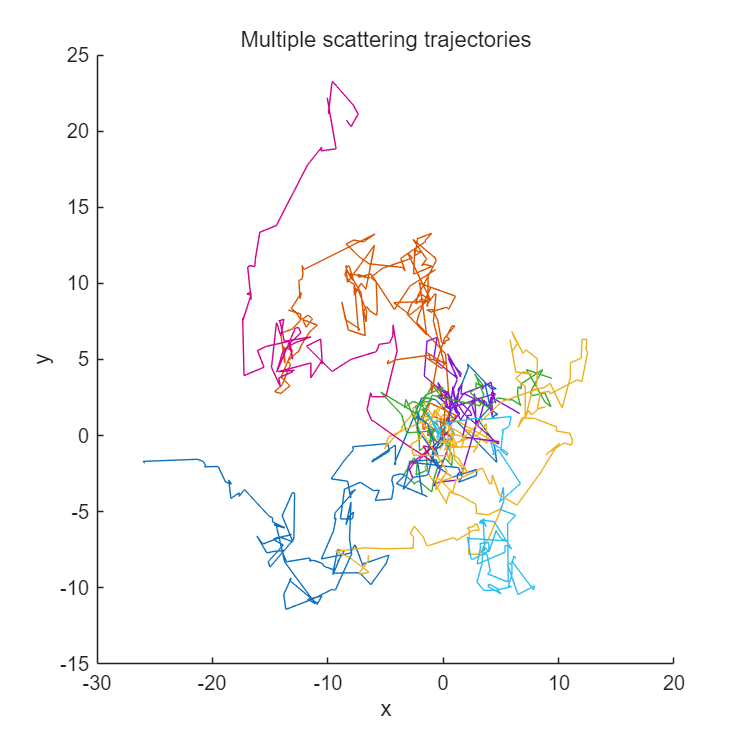


clear;
% 参数设置
typical_scattering_angle = 1;
propagation_time = 100;
number_of_paths = 10000;
system_size = 100;
number_of_bins = 100;
number_of_printed_trajectories = 10;

histogram_bin = system_size / number_of_bins;
half_system_size = 0.5 * system_size;
% analy为true时画出解析结果
analy = true;
if system_size < 0
    system_size = -system_size;
    analy = true;
end

% 向量化生成所有路径
theta0 = rand(1, number_of_paths) * 2 * pi; % 初始角度
theta = typical_scattering_angle * randn(propagation_time, number_of_paths); % 每步转角
path_length = exprnd(1, propagation_time, number_of_paths); % 每步长度,指数分布1

theta_cum = cumsum([theta0; theta], 1); % 累积角度 (size: propagation_time+1 x number_of_paths)
cos_theta = cos(theta_cum);
sin_theta = sin(theta_cum);

% 步长补零首行
path_length_pad = [zeros(1, number_of_paths); path_length];

% 计算每步增量
dx = path_length_pad .* cos_theta;
dy = path_length_pad .* sin_theta;

% 计算所有路径的坐标
position_x = cumsum(dx, 1); % propagation_time+1 x number_of_paths
position_y = cumsum(dy, 1);

% 均方位移
r2 = mean(position_x.^2 + position_y.^2, 2);

% 轨迹作图（前 number_of_printed_trajectories 条）
figure; hold on;
for j = 1:number_of_printed_trajectories
    plot(position_x(:, j), position_y(:, j));
end
xlabel('x'); ylabel('y'); title('Multiple scattering trajectories');
hold off;

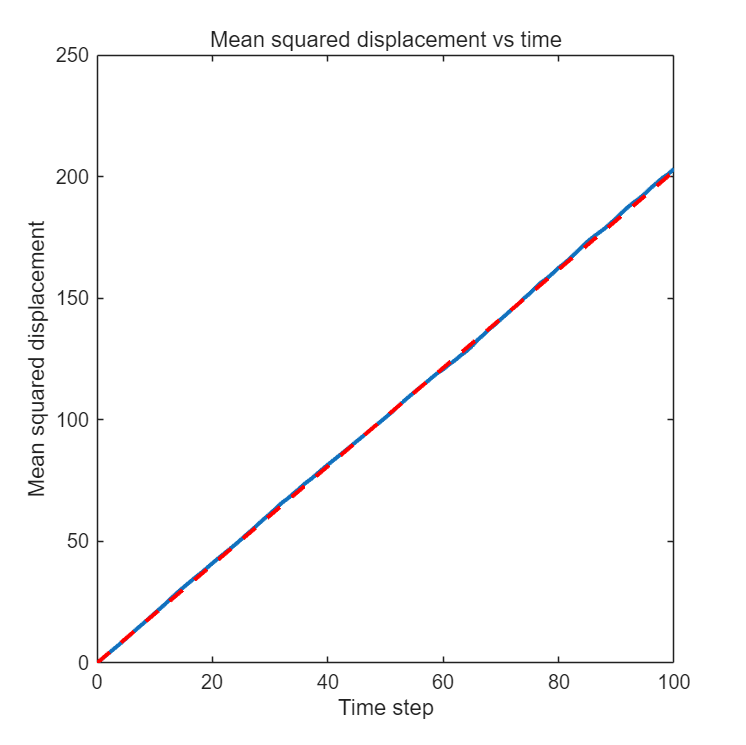


% 作图：均方位移随时间
diffusion_coefficient = 1 / (1 - exp(-0.5 * typical_scattering_angle^2));
figure;
plot(0:propagation_time, r2, 'LineWidth', 2);
ax1 = gca;
xlabel('Time step'); ylabel('Mean squared displacement');
title('Mean squared displacement vs time');
if analy
    hold on
    plot(0:propagation_time, 2 * (0:propagation_time) * diffusion_coefficient, 'r--', 'LineWidth', 2,'DisplayName','Analytic');
    % xlabel('Time step'); ylabel('Analytic mean squared displacement');
    % title('Analytic mean squared displacement vs time');
    hold off
end

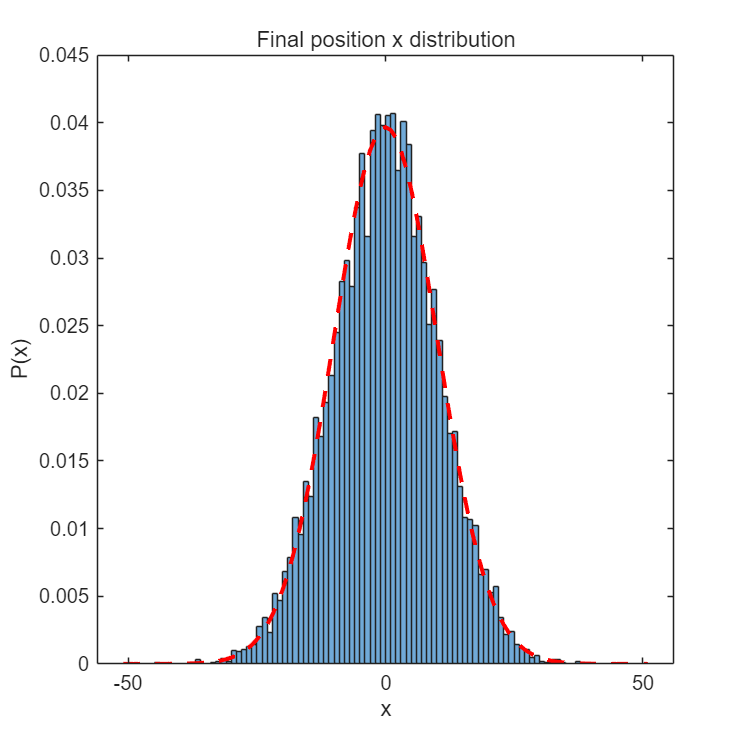

% 统计终点分布

final_x = position_x(end, :);
final_y = position_y(end, :);
binEdge = (-system_size/2-1) : (system_size/2+1);
% 作图：终点 x 分布

histogram(final_x, binEdge, 'Normalization','probability')
xlabel('x'); ylabel('P(x)');
title('Final position x distribution');
if analy
    hold on
    px_analytic = exp(-0.5 * binEdge.^2 / (diffusion_coefficient * propagation_time)) ...
        / sqrt(2 * pi * diffusion_coefficient * propagation_time);
    plot(binEdge, px_analytic, 'r--', 'LineWidth', 2,'DisplayName','Analytic');
    hold off
end

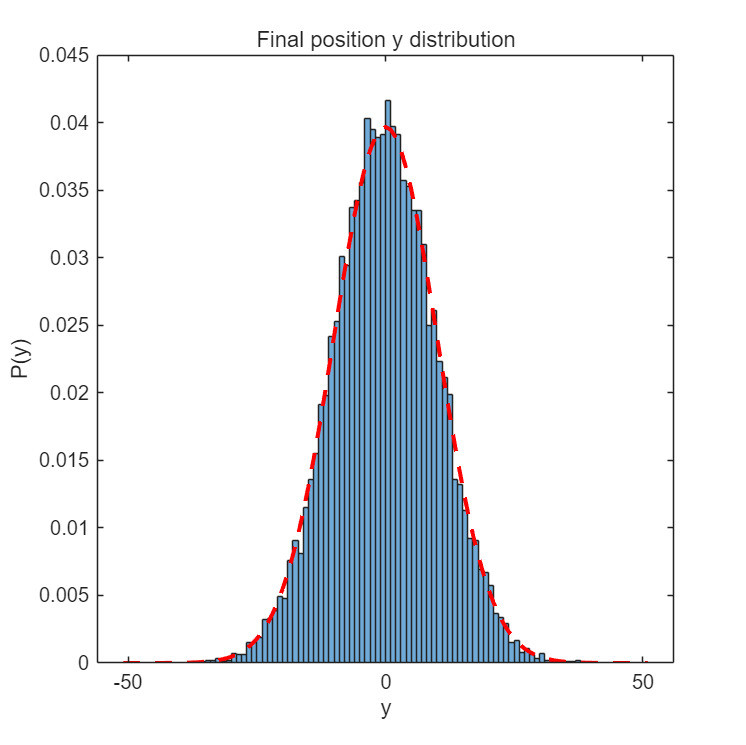

% 作图：终点 y 分布
figure;
histogram(final_y, binEdge, 'Normalization','probability')
xlabel('y'); ylabel('P(y)');
title('Final position y distribution');
if analy
    hold on
    py_analytic = exp(-0.5 * binEdge.^2 / (diffusion_coefficient * propagation_time)) ...
        / sqrt(2 * pi * diffusion_coefficient * propagation_time);
    plot(binEdge, px_analytic, 'r--', 'LineWidth', 2,'DisplayName','Analytic');
    hold off
end